load("wine.data")
wine(:,1)

ans =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


wine(:,1)=[]

wine = 	1.0e+03 *

    0.0142    0.0017    0.0024    0.0156    0.1270    0.0028    0.0031    0.0003    0.0023    0.0056    0.0010    0.0039    1.0650
    0.0132    0.0018    0.0021    0.0112    0.1000    0.0027    0.0028    0.0003    0.0013    0.0044    0.0011    0.0034    1.0500
    0.0132    0.0024    0.0027    0.0186    0.1010    0.0028    0.0032    0.0003    0.0028    0.0057    0.0010    0.0032    1.1850
    0.0144    0.0019    0.0025    0.0168    0.1130    0.0039    0.0035    0.0002    0.0022    0.0078    0.0009    0.0035    1.4800
    0.0132    0.0026    0.0029    0.0210    0.1180    0.0028    0.0027    0.0004    0.0018    0.0043    0.0010    0.0029    0.7350
    0.0142    0.0018    0.0025    0.0152    0.1120    0.0033    0.0034    0.0003    0.0020    0.0067    0.0011    0.0029    1.4500
    0.0144    0.0019    0.0025    0.0146    0.0960    0.0025    0.0025    0.0003    0.0020    0.0053    0.0010    0.0036    1.2900
    0.0141    0.0022    0.0026    0.0176    0.1210    0.0026    

wine(:,1)

ans =    14.2300
   13.2000
   13.1600
   14.3700
   13.2400
   14.2000
   14.3900
   14.0600
   14.8300
   13.8600


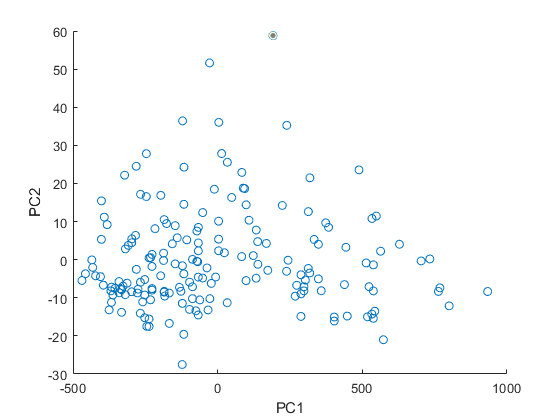


[coeff, score, latent, ~, ~, mu]  = pca(wine);
figure;
h=scatter(score(:,1), score(:,2));
subjects = ["Alcohol", "Malic acid", "Ash", "Alcalinity of ash", "Magnesium", "Total phenols", "Flavanoids", "Nonflavanoid phenols", "Proanthocyanins","Color intensity","Hue","OD280/OD315 of diluted wines","Proline"];
% subjects = ["Japanese", "social studies", "math", "science", "music", "art", "physical training", "industrial arts and homemaking", "english"];
for i = 1:13
    row = dataTipTextRow(subjects(i),wine(:, i));
    h.DataTipTemplate.DataTipRows(end+1) = row;
end
xlabel('PC1');
ylabel('PC2');

latent

latent = 	1.0e+04 *

    9.9202
    0.0173
    0.0009
    0.0005
    0.0001
    0.0001
    0.0000
    0.0000
    0.0000
    0.0000


cumsum(latent)/sum(latent)

ans =     0.9981
    0.9998
    0.9999
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


coeff(:,1)

ans =     0.0017
   -0.0007
    0.0002
   -0.0047
    0.0179
    0.0010
    0.0016
   -0.0001
    0.0006
    0.0023


coeff(:,2)

ans =     0.0012
    0.0022
    0.0046
    0.0265
    0.9993
    0.0009
   -0.0001
   -0.0014
    0.0050
    0.0151
